# Fuzzy ART の実装

教師なし分類器であるFuzzyARTの実装を行う

## データセットの作成

本実験では，2次元点群を対象とする．

また，クラス分類を容易にするため，中心からある程度の範囲に収まるような円を考えそれを使用する．

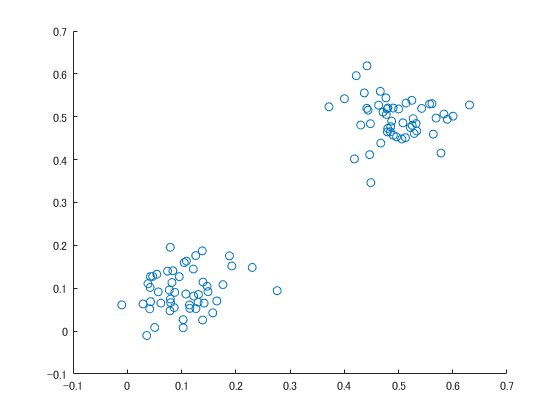

% Class1 Data
mu = [0.1 0.5];
sigma = [0.05 0.05];
dataNum = 100;
dataDim = 2;
I = zeros(dataDim*2, dataNum);

for i = 1 : dataNum
    paramIdx = mod(i, length(mu)) + 1;
    data = normrnd(mu(paramIdx), sigma(paramIdx), [2 1]);
    I(:, i) = [data; 1-data];
end
scatter(I(1,:), I(2,:));

% Class2 Data

## Preprocessing

ここでは，データの前処理を行う．

基本的には正規化を施し，データとする．

% for i = 1:length(I)
%     I(:, i) = I(:, i) / norm(I(:, i));
% end
% scatter(I(1,:), I(2,:));

## Initialize

ここでは各パラメータの初期化を行う．

initClassNum = 1;
rho = 0.5;
alpha = 1;
eta = 0.9;
dataChoiceNum = zeros(size(I, 2), 1);

W = zeros(initClassNum, size(I, 1)) + 1;

## Search

while (min(dataChoiceNum) == 0)
    % データの選択
    idx = unidrnd(size(I, 2));
    dataChoiceNum(idx) = dataChoiceNum(idx) + 1;
    
    % Choise step
    t = zeros(size(W, 1), 1);
    for i = 1 : size(W, 1)
        t(i) = norm(fuzzyConjunction(I(:, idx), W(i, :))) / (alpha + norm(W(i, :)));
    end
    [~, winnerIdx] = sort(t);
    
    % Match step
    resonanceFlg = false;
    for i = transpose(winnerIdx)
        if rho <= norm(fuzzyConjunction(I(:, idx), W(i, :))) / norm(I(:, idx))
            resonanceFlg = true;
            break;
        end
    end
    % Adaptaion 
    if (resonanceFlg)
        W(i, :) = eta * transpose(fuzzyConjunction(I(:, idx), W(i, :))) + (1 -eta) * W(i, :);
    else
        W = [W; transpose(I(:, idx))];
    end
end

## 結果の確認

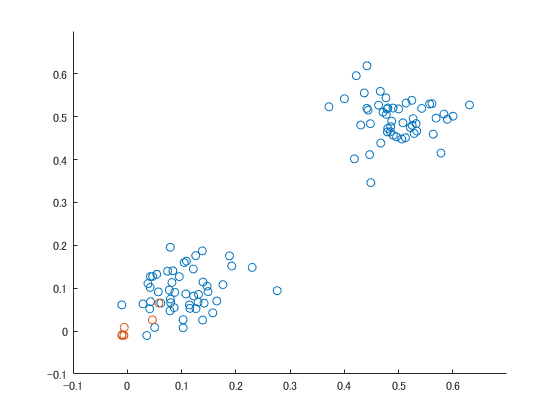

scatter(I(1,:), I(2,:));
hold on;
scatter(W(:, 1), W(:, 2));

## 参考文献

[1] Comparative Analysis of Fuzzy ART and ART-2A Network Clustering Performance

[2] 対戦型ゲームのための階層型ファジィART学習システム